# Equal sharing of resources

Num_individuals=100;
Num_time_steps=120; %300 when m_nur=2
nut_init=50;
m_for=1;
m_nur=2;
mu=50;
nutrition_levels = nut_init*(0.9 + 0.2*rand(Num_individuals,1))

nutrition_levels =    52.0649
   47.5668
   47.8442
   51.6319
   48.4749
   53.3912
   52.5759
   50.2699
   48.1383
   45.8969



%In our simulation, nursing will be denoted by 1, and foraging by 2
worker_roles = ones(Num_individuals,Num_time_steps); %Initially workers all nurse until they are stimulated to go forage
food = 0; %Initialising no food available
R=4; %Amount of food collected by each forager
num_foragers=zeros(1,Num_time_steps); %Initialising number of foragers

for time = 1:Num_time_steps
    for worker = 1:Num_individuals
        perception_err = -1+ 2*rand(); %Error with which they perceive their own hunger
        if nutrition_levels(worker) + perception_err<= mu
            worker_roles(worker,time) = 2;
        else
            worker_roles(worker,time)=1;
        end

        if worker_roles(worker,time)==1
            nutrition_levels(worker) =nutrition_levels(worker)-m_nur+food;
        else %if the role was 2
            nutrition_levels(worker) = nutrition_levels(worker)-m_for+food;
        end

    end
        num_foragers(1,time) = sum(worker_roles(:,time)==2);
        food = R*num_foragers(1,time)/Num_individuals;
end

## Number of nursers and foragers over time plot

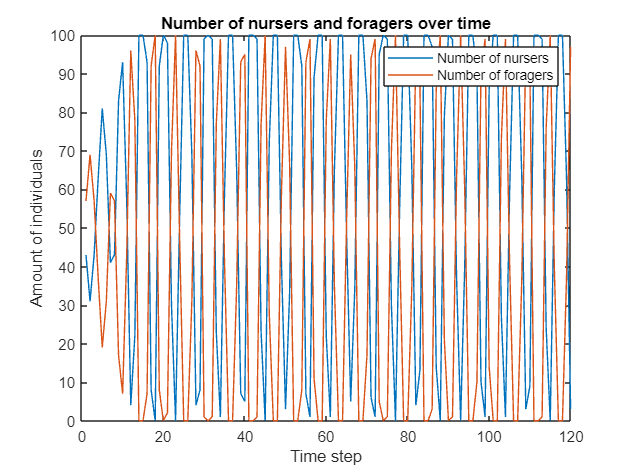

plot(100-num_foragers)
hold on
plot(num_foragers)
hold off
title('Number of nursers and foragers over time')
ylabel('Amount of individuals')
xlabel('Time step')
legend('Number of nursers', 'Number of foragers')

## Nutrition levels of the nursers and foragers plot

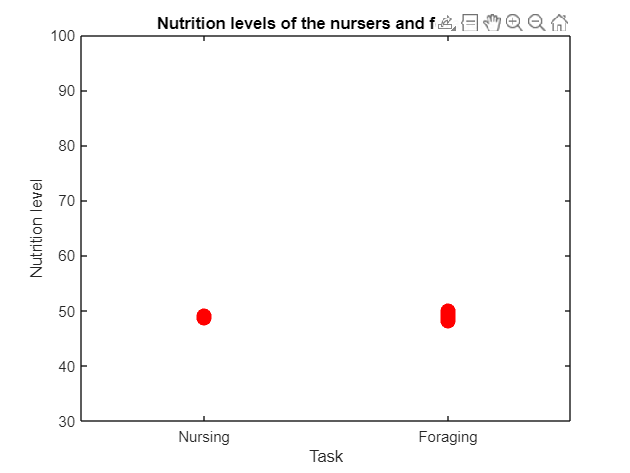

x = worker_roles(:,120);
x_categorical = categorical(x, [1 2], {'Nursing', 'Foraging'});
plot(x_categorical, nutrition_levels, 'r.', 'MarkerSize', 30)

xlabel('Task')
ylim([30, 100])
ylabel('Nutrition level')
title('Nutrition levels of the nursers and foragers')

## Calculation of division of labour

repetitions = zeros(Num_time_steps,1);

for j = 2:Num_time_steps
    for i=1:Num_individuals
           if worker_roles(i,j)==worker_roles(i,j-1)
                 repetitions(j)=repetitions(j)+1;
           end
    end
end

q = repetitions/Num_individuals

q =          0
    0.8600
    0.8400
    0.7800
    0.8000
    0.7800
    0.5600
    0.5800
    0.4200
    0.7600


p1 = num_foragers./Num_individuals

p1 =     0.5700    0.6900    0.5700    0.3700    0.1900    0.3100    0.5900    0.5700    0.1700    0.0700    0.4300    0.9600    0.7800         0         0    0.0700    0.9200    1.0000    0.0800         0    0.0200    0.7000    1.0000    0.4700         0         0    0.3100    0.9600    0.9200    0.0100         0    0.0100    0.7700    0.9900    0.4200         0         0    0.3500    0.9300    0.9500         0         0    0.0100    0.7700    1.0000    0.2800         0         0    0.5900    0.9700


p2 = (100-num_foragers)./Num_individuals

p2 =     0.4300    0.3100    0.4300    0.6300    0.8100    0.6900    0.4100    0.4300    0.8300    0.9300    0.5700    0.0400    0.2200    1.0000    1.0000    0.9300    0.0800         0    0.9200    1.0000    0.9800    0.3000         0    0.5300    1.0000    1.0000    0.6900    0.0400    0.0800    0.9900    1.0000    0.9900    0.2300    0.0100    0.5800    1.0000    1.0000    0.6500    0.0700    0.0500    1.0000    1.0000    0.9900    0.2300         0    0.7200    1.0000    1.0000    0.4100    0.0300



D = [];
for i =1:length(q)
    D(i) = q(i)./(p1(i).^2 + p2(i).^2) - 1;
end

## Division of labour over time plot

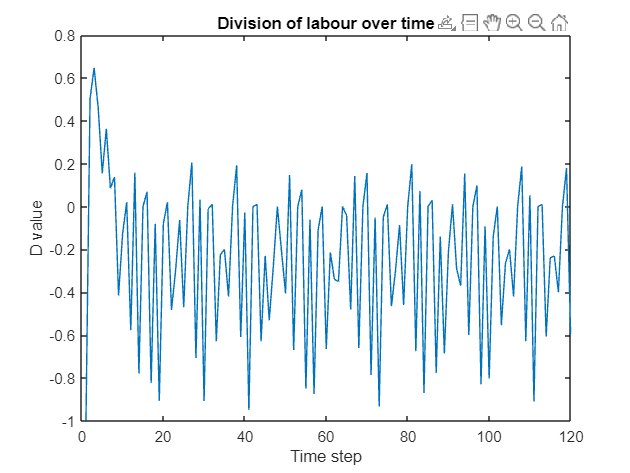

plot(1:Num_time_steps, D)
title('Division of labour over time')
ylabel('D value')
xlabel('Time step')